## Example 1: Linear Regression

**Objective:** Perform univariate (single input factor) linear regression on sample data with and without a parameter constraint.

For linear regression, find unknown parameters *a**0* (slope) and *a**1* (intercept) to minimize the difference between measured *y* and predicted *y**fit*.

**Data**

x=[4,5,2,3,−1,1,6,7]

y=[0.3,0.8,−0.05,0.1,−0.8,−0.5,0.5,0.65]

**Linear Equation**

yfit=a0x+a1

**Minimize Objective**

mina0,a1n∑i=1(yi−yfit,i)^2

where *n* is the length of *y* and *a**0* and *a**1* are adjusted to minimize the sum of the squared errors.

Report the parameter values, the *R**2* value of fit, and display a plot of the results. Enforce a constraint with the intercept>-0.5 and show the effect of that constraint on the regression fit compared to the unconstrained least squares solution.

% Create Data
x = [4,5,2,3,-1,1,6,7];
y = [0.3,0.8,-0.05,0.1,-0.8,-0.5,0.5,0.65];

% Linear Regression
mdl = fitlm(x,y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat      pValue  
                   ________    ________    _______    _________

    (Intercept)    -0.54323     0.11507    -4.7211    0.0032544
    x1              0.19799    0.027408     7.2239    0.0003568


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.194
R-squared: 0.897,  Adjusted R-Squared: 0.88
F-statistic vs. constant model: 52.2, p-value = 0.000357

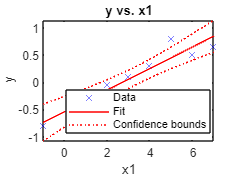

plot(mdl)

yfit = mdl.Coefficients.Estimate(2)*x+mdl.Coefficients.Estimate(1);

R_squared = rsq(y,mdl.Coefficients.Estimate(2)*x+mdl.Coefficients.Estimate(1))

R_squared = 0.9098



%% TODO:: Look at poly fit and possible other solutions to this
% Polyfit Regression
% [p,S] = polyfit(y,x,1)
% plot(x,x*mdlp(2)+mdlp(1))

## Exercise 2: Multiple Linear Regression

**Objective:** Perform multiple linear regression on sample data with two inputs.

For linear regression, find unknown parameters *a**0*-*a**2* to minimize the difference between measured *y* and predicted *y**fit*.

**Data**

x0=[4,5,2,3,−1,1,6,7]

x1=[3,2,3,4,3,5,2,6]

y=[0.3,0.8,−0.05,0.1,−0.8,−0.5,0.5,0.65]

**Linear Equation**

yfit=a0x0+a1x1+a2

**Minimize Objective**

mina0,a1n∑i=1(yi−yfit,i)^2

where *n* is the length of *y* and *a**0**-a**2* are adjusted to minimize the sum of the squared errors.

Report the parameter values, the *R**2* value of fit, and display a plot of the results.

% Create Data
x0 = [4,5,2,3,-1,1,6,7];
x1 = [3,2,3,4, 3,5,2,6];
y = [0.3,0.8,-0.05,0.1,-0.8,-0.5,0.5,0.65];
one_array = ones(1,8);

% Linear fit
X = [x0; x1; ones(1,length(x0))]';
a = X\y';
yfit = a(1)*x0 + a(2)*x1 + a(3);
fprintf('R^2 = %.2f\n',rsq(y,yfit))

R^2 = 0.94


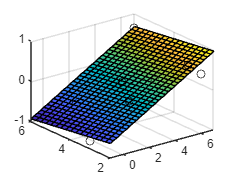


% plot data
figure
scatter3(x0,x1,y,'k','o')
hold on
x0t = -1:0.25:7;
x1t = 2:0.25:6;
[X0,X1] = meshgrid(x0t,x1t);
Yt = a(1)*X0 + a(2)*X1 + a(3);
surf(X0,X1,Yt)
hold off

## Exercise 3: Scale-up

For large problems, it is important to know how a linear regression package performs with larger data sets on CPU and GPU hardware. The IPython Notebook below evaluates the clock time for problems up to 108 samples.

%% Python has many ways to solve a linear fit. We show only two ways. (There may be more ways but I only know of these)

table = [];
table1 = [];

% Polyfit Method
test_time = 20.0;
w = rand();
b = rand();
n = 100;
start = tic;
while toc(start) <= test_time
    x = linspace(0,100,n);
    y = w * x + b;

    % Add noise
    noise = randn(1,n);
    y = y + noise;
    
    t0 = tic;
    polyfit(x,y,1);
    t1 = toc(t0);
    %fprintf('%d %f\n',n,t1)
    table = [table, t1];

    n = n*2; % Double number of data points
end

% fitlm
test_time = 20.0;
w = rand();
b = rand();
n = 100;
start = tic;
while toc(start) <= test_time
    x = linspace(0,100,n);
    y = w * x + b;
    
    % Add Gaussian noise
    noise = randn(1,n);
    y = y + noise;

    t0 = tic;
    lm = fitlm(x',y');
    t1 = toc(t0);
    %fprintf('%d %d\n', n, t1);
    table1 = [table1, t1];
    
    n = n * 2; % Double number of data points
end

100 2.064001e+00
200 1.041750e-01
400 6.581670e-02
800 3.223140e-02
1600 1.576156e-01
3200 1.498600e-02
6400 8.308600e-03
12800 1.420520e-02
25600 1.563810e-02
51200 1.411420e-02
102400 2.087850e-02
204800 3.660160e-02
409600 6.628680e-02
819200 1.169976e-01
1638400 2.147909e-01
3276800 4.044472e-01
6553600 7.635155e-01
13107200 1.462671e+00
26214400 4.035613e+00
52428800 7.663301e+00


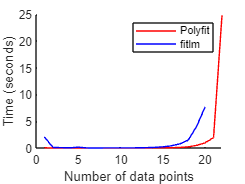

figure
hold on
plot(table, 'r')
plot(table1, 'b')
xlabel('Number of data points')
ylabel('Time (seconds)')
legend('Polyfit', 'fitlm')

function r2 = rsq(y1,y2)
    yresid = y1 - y2;
    SSresid = sum(yresid.*yresid);
    [V,md ] = var(y1);
    [r,c]=size(y1);
    SStotal = c*V;
    r2 = 1 - SSresid./SStotal;
end